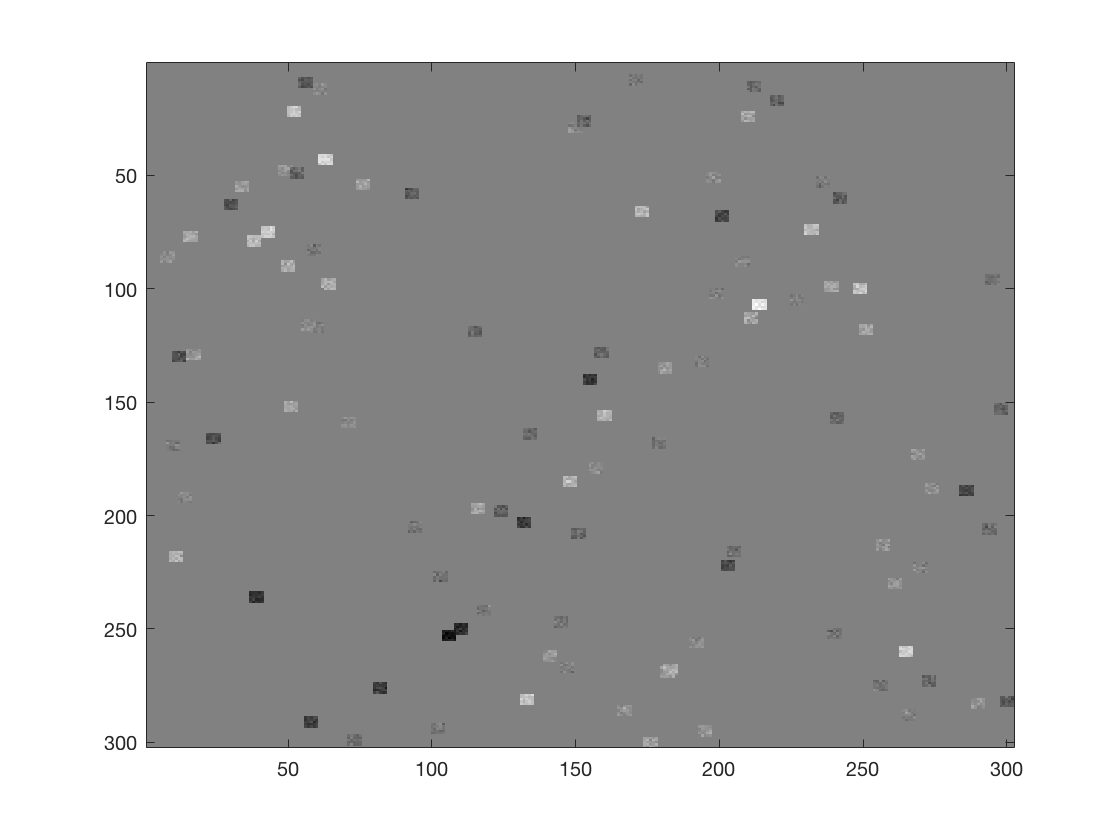

%1(a)
img = zeros(304,304);

img(2:303,2:303)=dat;

medfiltimg = zeros(302,302);

x=[];
for i=2:303
    for j= 2:303
        x = img(i-1:i+1,j-1:j+1);
        x = x(:);
        x = sort(x);
        medfiltimg(i-1,j-1) = x(5);
    end
end

medfilt2img = medfilt2(dat);

figure
imagesc(dat);
colormap(gray);

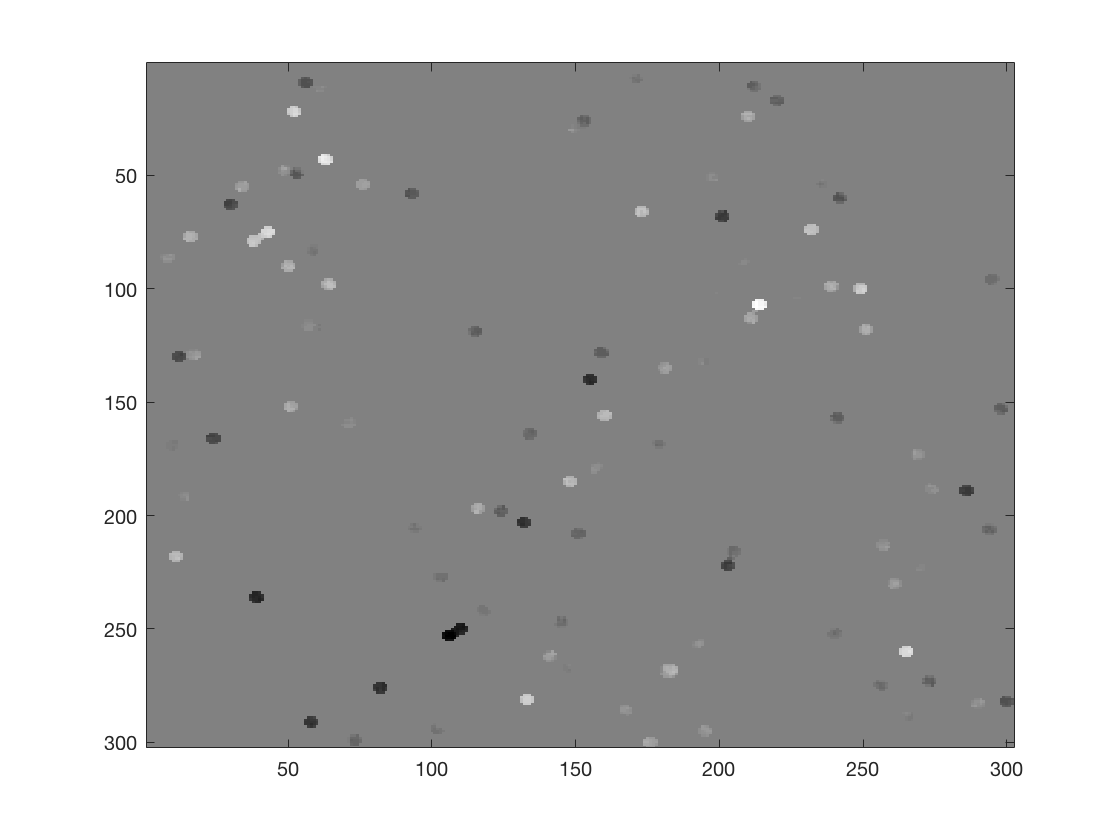

figure
imagesc(medfiltimg);
colormap(gray);

figure
imagesc(medfilt2img);
colormap(gray);

max(max(medfilt2img-medfiltimg))

ans = 0


%The two images are the same. This can be seen from the fact that max value
%int their difference is 0 which implies that the two images are exactly
%the same.

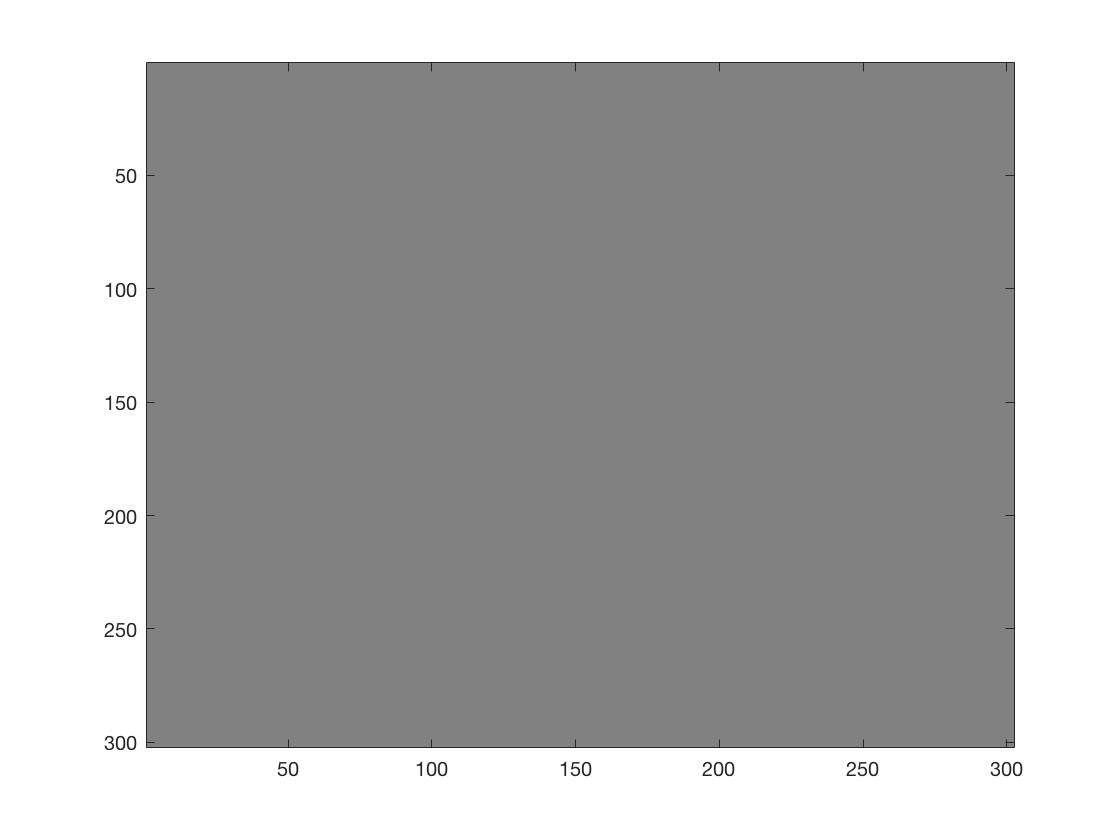

%1(b)

x = medfilt2(dat,[11,11]);
figure
imagesc(x);
colormap(gray);


%The minimum size of the filter that removes all of the "salt and pepper"
%in the image is 11.

%1(c)
% The minimum window that should guarantee that the salt and pepper is
% removed in such a case would be 8*8. This is because in the worst case,
% noise will generated in each pixel in the 5*5 window which will result in
% 25 pixels having noise. To remove this noise, the median of for each
% pixel must not have any noise which means all the noise pixels should
% fall to the right of the median which will happen in an 8*8 window but
% won't happen in a 7*7 window.

% My solution does not match what I found in the previous part since an 8*8
% window will only be sufficient for removing the salt and pepper
% for an isolated piece of salt and pepper and the given image consisted of
% many pieces of the salt and pepper noise that were close to each other.

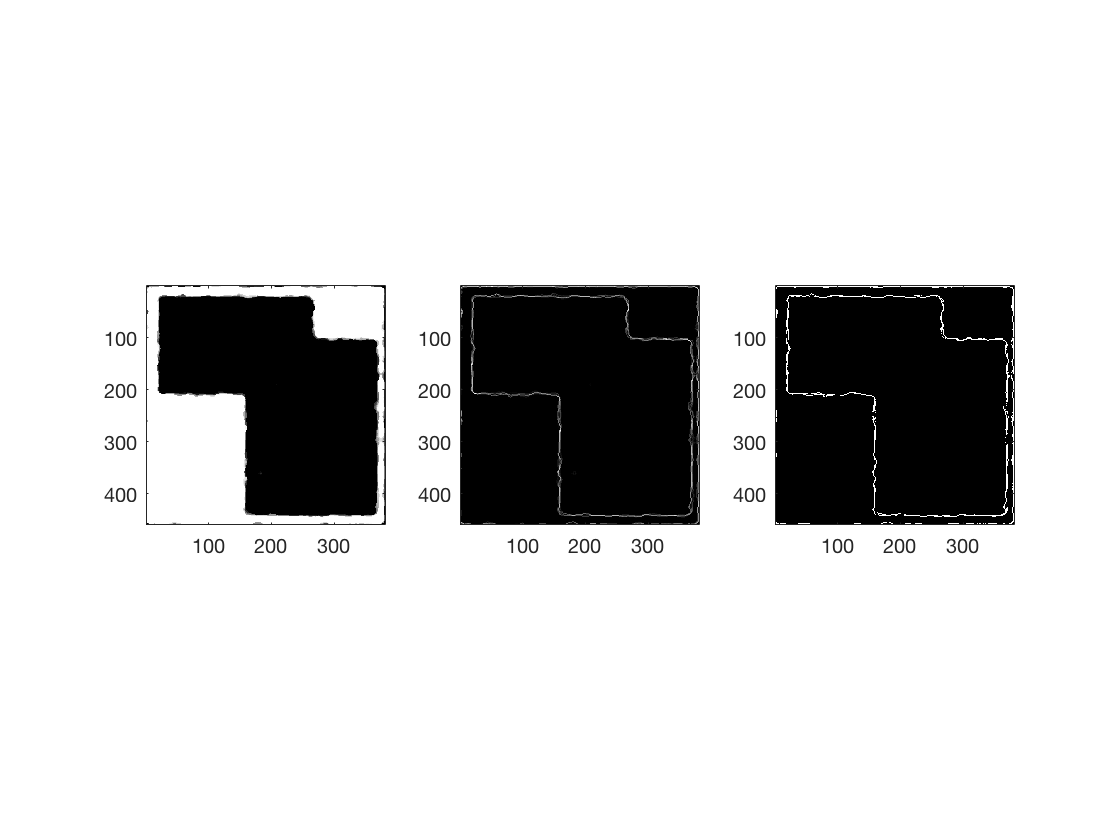

%2

img = medfilt2(dat_hough,[14,14]);

% To remove the artifact, I used median filtering. I used median filtering
% since it is a low pass filter and thus does a good job in removing the
% high frequency noise in the image. 

figure
subplot(1,3,1);
imagesc(img);
colormap(gray);
axis('square');

ky = zeros(3,3);
ky(2,1) = 1;
ky(2,3) = -1;
ky = 0.5*ky;
kx = zeros(3,3);
kx(1,2) = 1;
kx(3,2) = -1;
kx = 0.5*kx;

x = conv2(img, kx, 'same');
y = conv2(img, ky, 'same');
img = sqrt(x.^2 + y.^2);

subplot(1,3,2);
imagesc(img);
colormap(gray);
axis('square');

% To estimate the edges, I used a central difference filter in both the x
% and y directions and then using the results, calculated the length of
% the gradient in the image. I used this method because finding the
% gradient in an image gives a very good estimate of potential edge pixels.

img = img>12;

% To convert the image into a binary image, I used a threshold below which
% all pixel are 0 and above which all pixels are 1.

subplot(1,3,3);
imagesc(img);
colormap(gray);
axis('square');

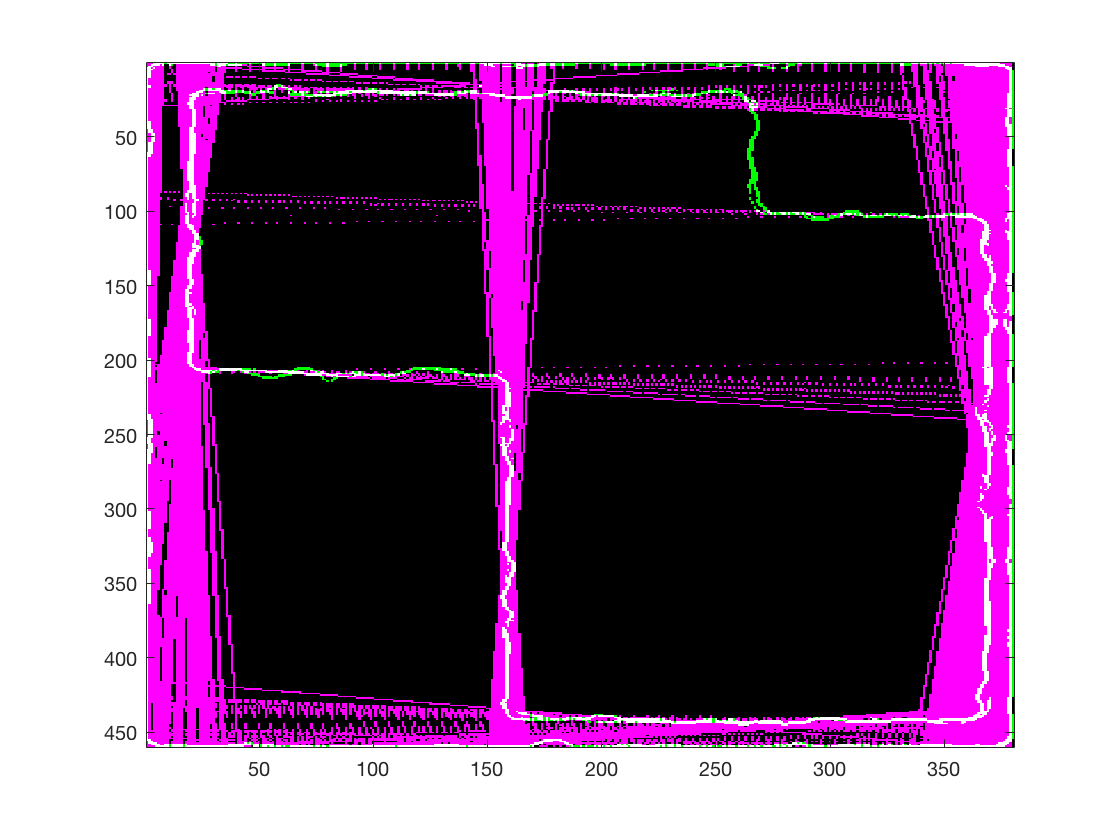


[himg, theta, r] = hough_trans(img);

maxint=max(max(himg));
[i, j] = find(himg > 0.14*maxint);

theta_rad = theta*pi/180;

slopes = -1*cos(theta_rad(j))./sin(theta_rad(j));
intercepts = r(i)./sin(theta_rad(j));

img_lines = zeros(size(img));
n_lines = length(slopes);
for i = 1:n_lines
  xval = [1:0.1:size(img,1)]'; 
  yval = intercepts(i) + xval*slopes(i);
  xval = round(xval);
  yval = round(yval);
  keep = yval< size(img,2) & yval>0;
  xval_keep = xval(keep);
  yval_keep = yval(keep);
  for index = 1:length(xval_keep)
     img_lines(xval_keep(index), yval_keep(index)) = 1;
  end
end


fused_img = imfuse(img, img_lines);
figure
imagesc(fused_img);
colormap(gray);

%3
img = img_circle;
hough_acum = zeros(540,720,3);
i_rng = size(img, 1);
j_rng = size(img, 2);

r = [48,50,52];

theta = 0:359;
for i=1:i_rng
  for j=1:j_rng
    if img(i,j) > 0
        for rad = 1:3
            for ang=theta
                theta_loop=ang*pi/180;
                x = i - r(rad)*cos(theta_loop);
                y = j - r(rad)*sin(theta_loop);
                if(round(x)>0 & round(x)<=size(img,1) & round(y)>0 & round(y)<=size(img,2))
                    hough_acum(round(x),round(y),rad) = hough_acum(round(x),round(y),rad)+1;
                end
            end
        end
    end
  end
end

[s,bestr] = max([max(max(hough_acum(:,:,1))),max(max(hough_acum(:,:,2))),max(max(hough_acum(:,:,3)))]);

r(bestr)

ans = 48

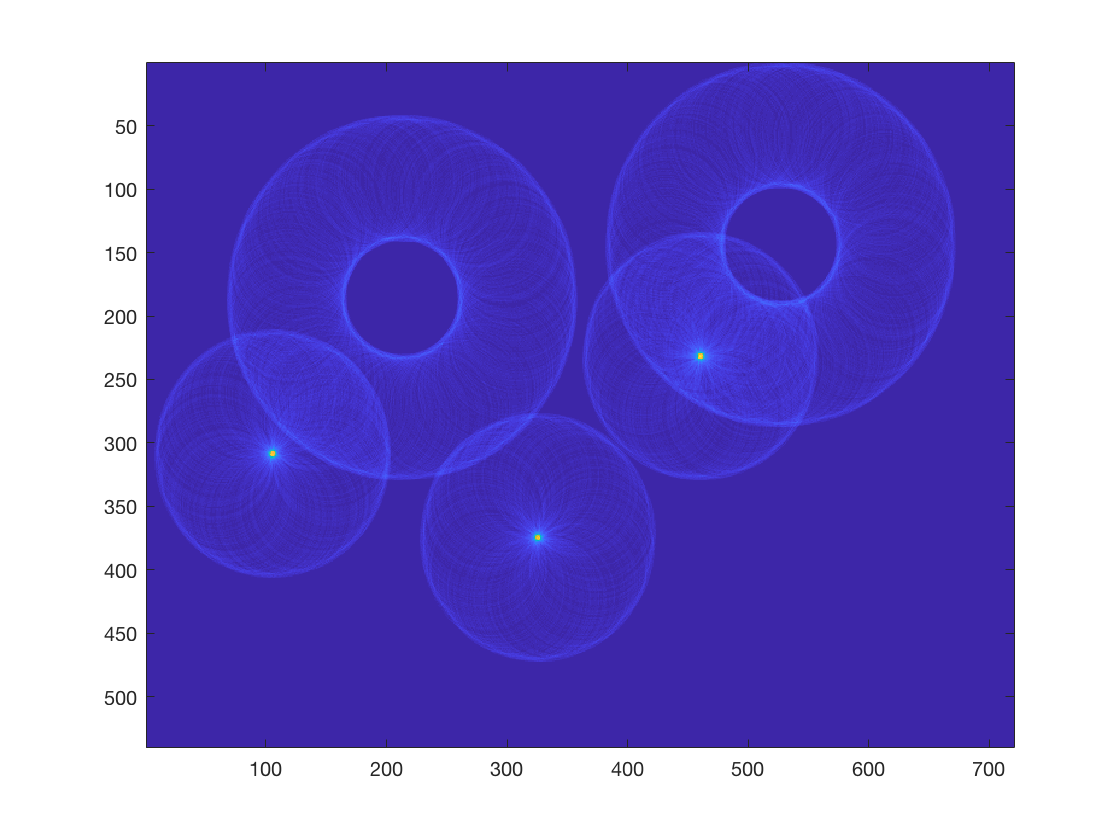

% The best radius is 48.

hough_acum_bestr = hough_acum(:,:,bestr)>(0.75*max(max(hough_acum(:,:,bestr))));

figure
imagesc(hough_acum(:,:,bestr));

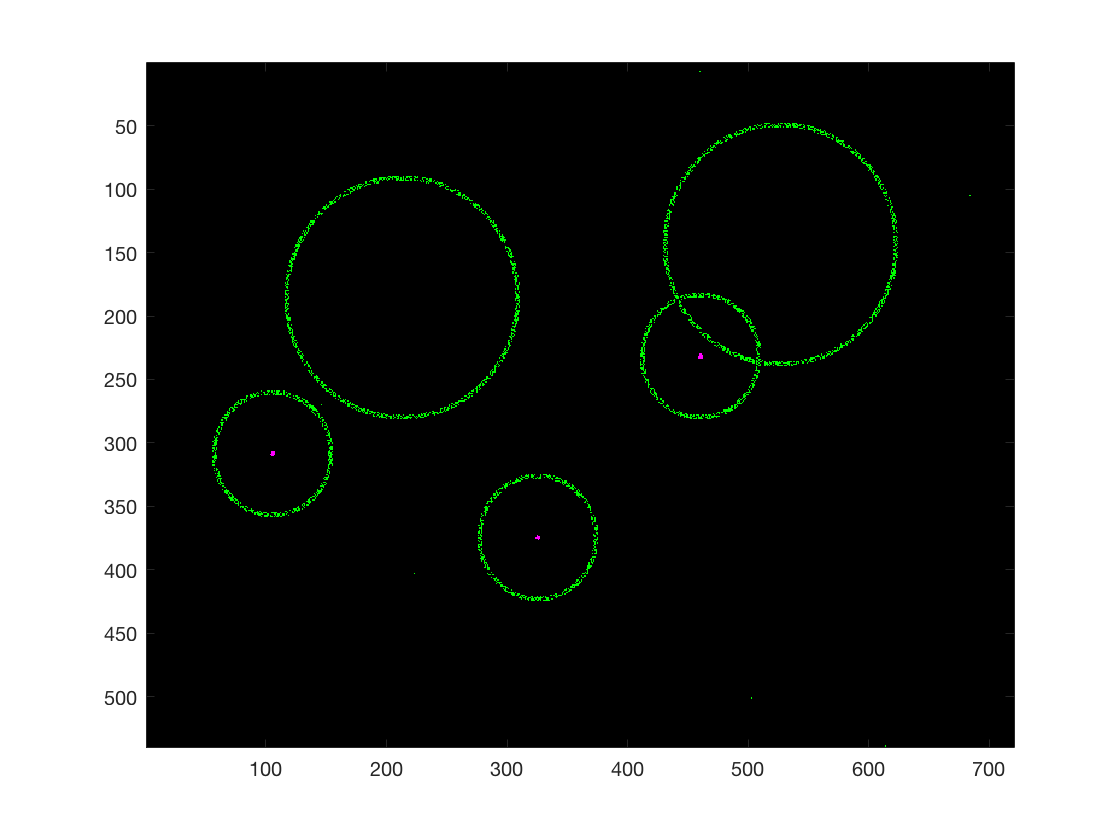


fused = imfuse(img,hough_acum_bestr);

figure
imagesc(fused);